# Homework 4

***Ryan Campbell, Christian Molina***

*Math 128A 2021 Summer Session 2 *

*Due Tuesday, 09/07/2021, 11:59 PM 	*	

## **Problem 1**

**(a) (45 points) **Let $f$ be a 2$\pi$-periodic function defined by the Fourier series 


$$f(x) = \sum_{k=-\infty}^\infty c_k \exp(ikx).$$
					

Suppose that $f(x)$ is real valued, which means that $c_{-k} = c ̄_k$, where the overbar represents the complex conjugate, $\overline{a + bi} = a - bi$. For real valued functions, the Fourier series can be written as 


$$f(x) = \frac{a_0}{2} + \sum_{k=1}^\infty a_k \cos(kx) + b_k \sin(kx).$$


Suppose you are given the complex coefficients $c_k$. Use that $\exp(i\theta ) = \cos(\theta ) + i \sin(\theta )$, and derive expressions for $a_k$ and $b_k$ in terms of $c_k$.

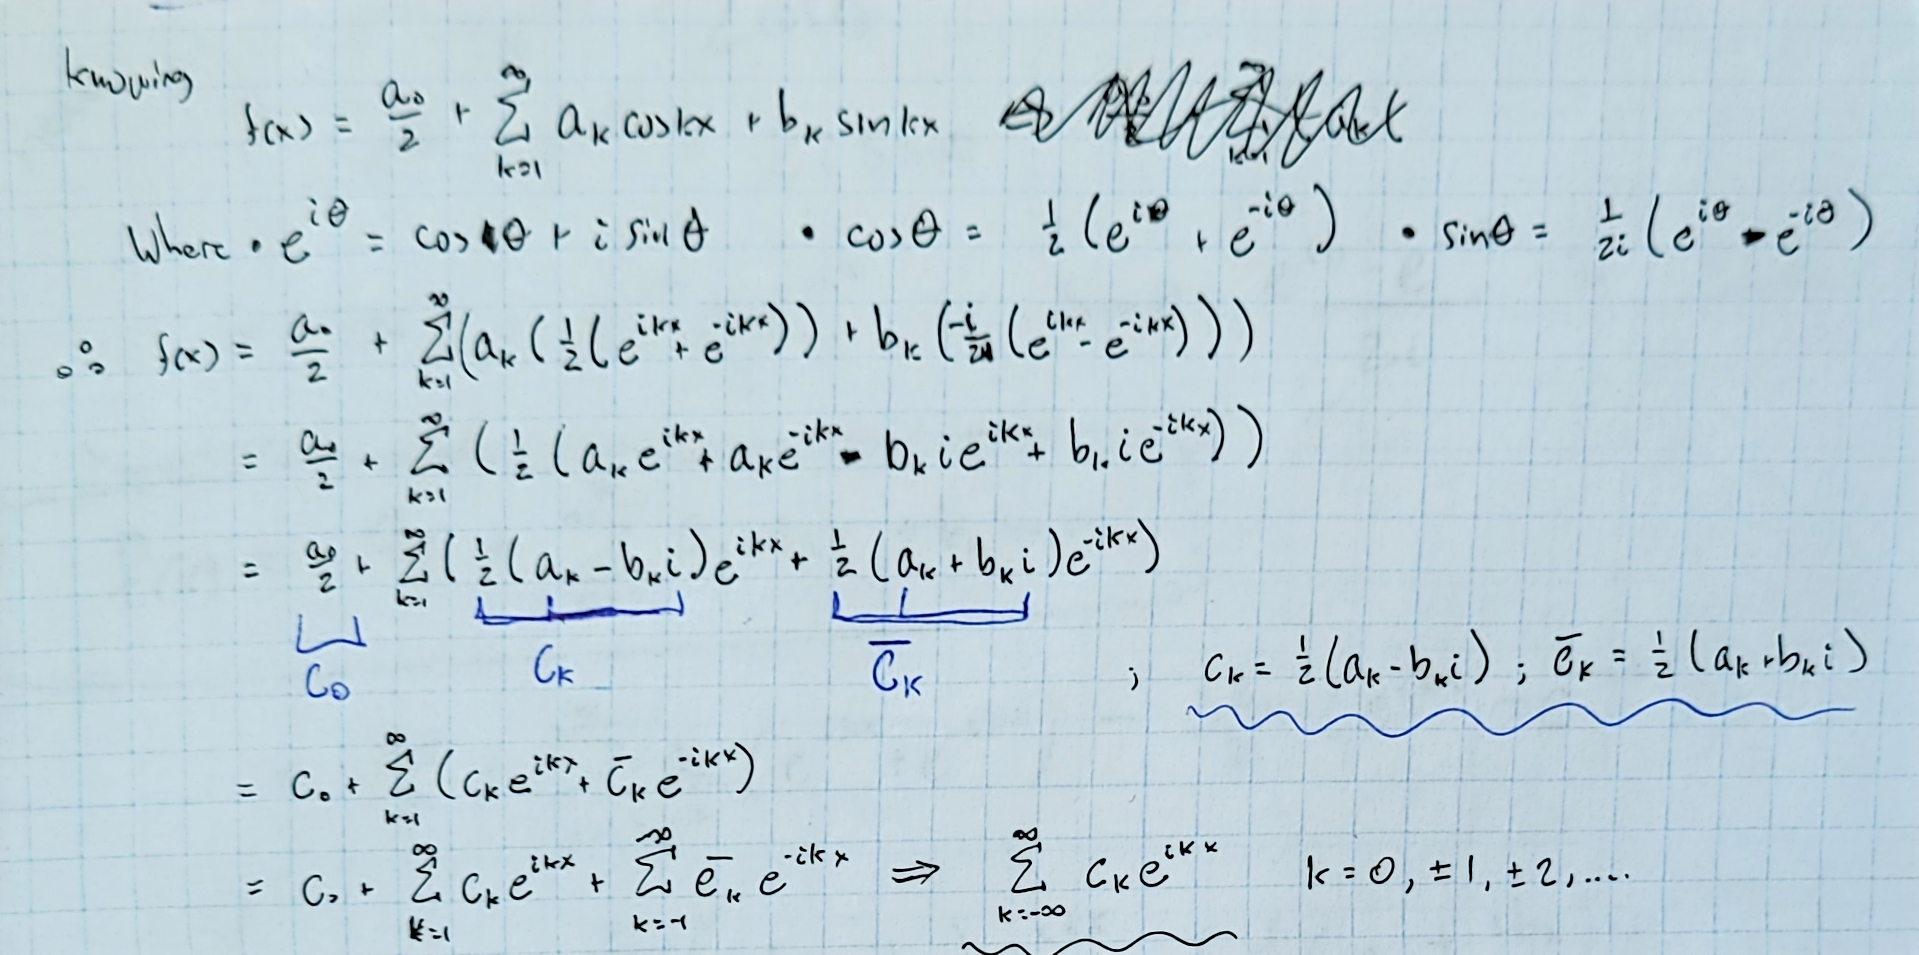  				

**(b)** Write a program which takes an input $x$ and the complex Fourier coefficients $c_k$ for $k = 0 \dots m$ of a real valued function, $f$ , and returns an approximation of $f(x)$. If these are the only non-zero coefficients, this will return $f(x)$ exactly. With that assumption, use the table of coefficients below and make a plot of $f(x)$.

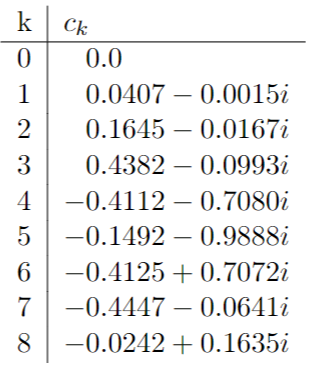

% Init the array above
c = [0.0 0.0407-0.0015i 0.1645-0.0167i 0.4382-0.0993i -0.4112-0.7080i -0.1492-0.9888i -0.4125+0.7072i -0.4447-0.0641i -0.0242+0.1635i];

m = length(c);
a = real(c);
b = imag(c);

syms x k; 
f_series(x) = (a(1)/2) + sum(a(2:end).*subs(cos(k.*x),k,1:m-1) + b(2:end).*subs(sin(k.*x),k,1:m-1))

$$f\_series(x) = \frac{329\,\cos\left(2\,x\right)}{2000}+\frac{2191\,\cos\left(3\,x\right)}{5000}-\frac{257\,\cos\left(4\,x\right)}{625}-\frac{373\,\cos\left(5\,x\right)}{2500}-\frac{33\,\cos\left(6\,x\right)}{80}-\frac{4447\,\cos\left(7\,x\right)}{10000}-\frac{121\,\cos\left(8\,x\right)}{5000}-\frac{167\,\sin\left(2\,x\right)}{10000}-\frac{993\,\sin\left(3\,x\right)}{10000}-\frac{177\,\sin\left(4\,x\right)}{250}-\frac{618\,\sin\left(5\,x\right)}{625}+\frac{442\,\sin\left(6\,x\right)}{625}-\frac{641\,\sin\left(7\,x\right)}{10000}+\frac{327\,\sin\left(8\,x\right)}{2000}+\frac{407\,\cos\left(x\right)}{10000}-\frac{3\,\sin\left(x\right)}{2000}$$

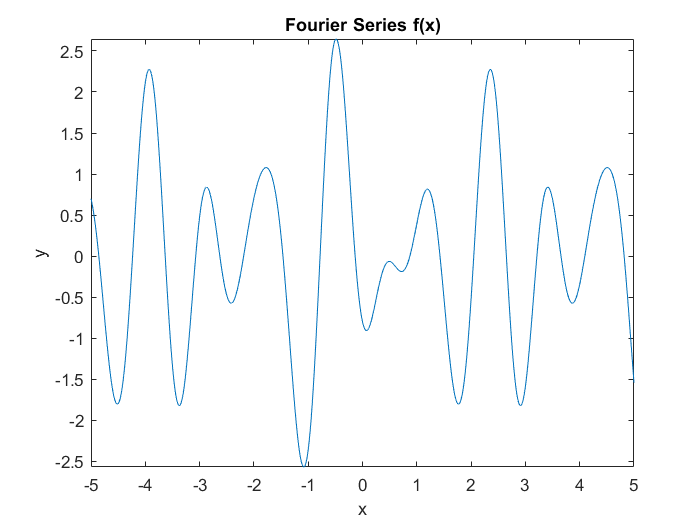


fplot(f_series)
title("Fourier Series f(x)")
xlabel("x"); ylabel("y");

## Problem 2

**(45 points)** The file `noisy_signal.txt` contains pairs of points $(t_k,f(t_k))$ which represents $1000$ equally spaced samples of the function $f$ on the time interval $[0, 2\pi)$. 				

**(a)** Make a plot of the data, $f$ vs. $t$. In Matlab, you can read in the data using the command `load` or `dlmread` and in Python use the `loadtxt` command in the `numpy` library.

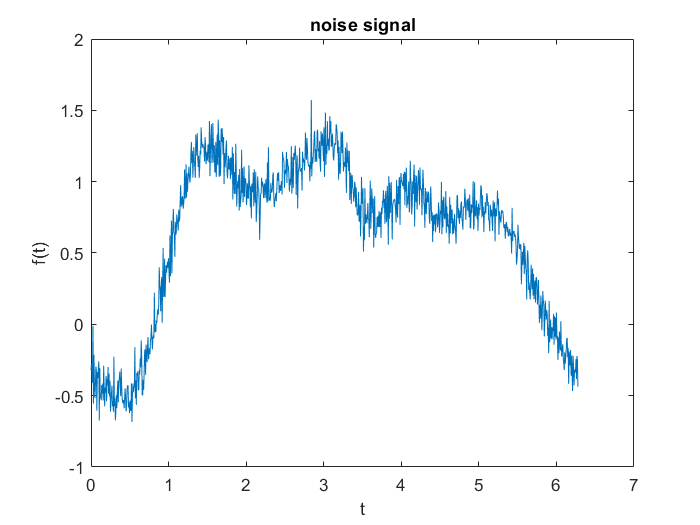

figure(2)
signal = readmatrix("noisy_signal.txt");
t_signal = signal(:,1);
f_signal = signal(:,end);
plot(t_signal,f_signal)
title("noise signal")
xlabel("t"); ylabel("f(t)");

**(b)** Use the `fft` command to compute the discrete Fourier transform of the data. Let $c_k$ be the complex-valued Fourier coefficients. Make a plot of $|c_k|$ vs. $k$ for $k = 0, \dots , 500$. Use log scales for both axes. In both Matlab and Python, you can evaluate the modulus of a complex number using the `abs` function. What can you conclude from this plot? 

There are $1000$ data points, and the `fft` will return $1000$ complex valued Fourier coefficients. The discrete Fourier coefficients from the `fft` algorithm (both Matlab and Python) are ordered as


$$(c_0,c_1,\dots,c_{500},c_{-499},c_{-498},\dots,c_{-2},c_{-1}).$$
	

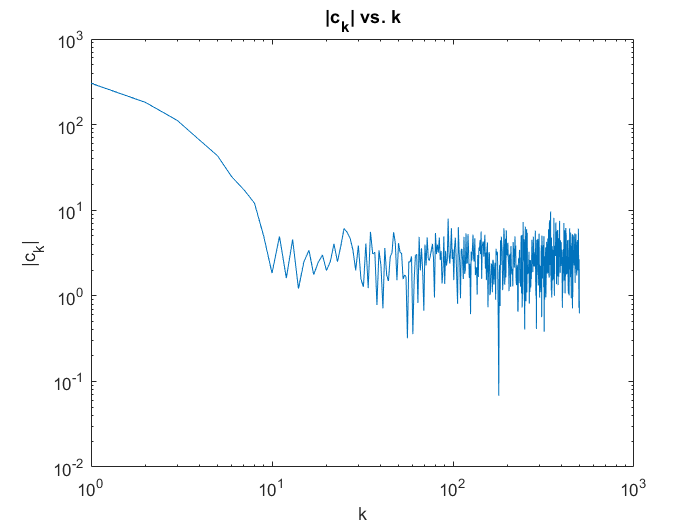

dft = fft(f_signal);
k = [0:499];

figure(3)
loglog(k,abs(dft(1:500)))
ylabel("|c_k|");xlabel("k");
title("|c_k| vs. k")

*With *$|c_k|$*vs. k graphed, we can see that coefficients that are |k| < 10 cause the noise in the data. *

**(c)** Let $f_s$ represent a smoothed version of the $f$ with the high frequency components removed. To smooth the data, filter out the high frequency components by setting the discrete Fourier coefficients, $c_k$, to zero for $|k| > 10$. To generate the time samples of $f_s$, use the `ifft` command. Plot $f_s$ vs. $t$. 

dft(10:end) = 0;
fs_signal = ifft(dft);

figure(4)
plot(t_signal,fs_signal)

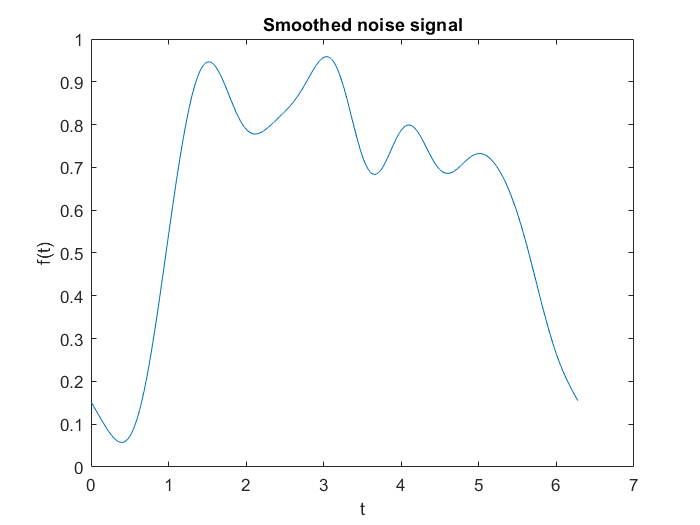

title("Smoothed noise signal")
xlabel("t"); ylabel("f(t)");

## Problem 3					

**(65 points)** Write programs to perform numerical integration of a given function, $f$, over a given interval $[a, b]$ using 

    *(i)* composite trapezoidal rule 

    *(ii)* composite Simpson’s rule 

    *(iii)* composite 3-point Gaussian quadrature (3 points per subinterval). 

Your routines should take as inputs: the integrand $f$, the endpoints $a$ and $b$, and the number the number of subintervals $n$. (Note: You did a version of *(i)* in homework 1, but adjust if needed to create a routine with these inputs.) 

**(a)**  Note that each quadrature rule requires a different number of points for a given number of subintervals. For each of the three composite quadrature rules how many function evaluations are required, assuming an efficient routine. (Your code may use more evaluations than this if done inefficiently, and that is fine.) 						

**(b)**  Apply each of these composite quadratures to approximate 


$$\int_0^{0.1} \frac{4}{1+x^2} dx.$$


Make a table of the results for $n = 2, 4, 8, 16, 32,$ and a table of the errors. How is the order of accuracy demonstrated in the table of errors? Make a log-log plot of the error vs. the number of function evaluations from part (a) for each of the three composite quadratures on the same axes. Comment on your results. 

N = [2 4 8 16 32]';
fb =@(x) 4 ./ (1 + x.^2);
exact_integral_b = integral(fb,0,0.1);

% Composite Trapezoidal Rule
approx_trap_b = [comp_trap(0,0.1,fb,2) comp_trap(0,0.1,fb,4) comp_trap(0,0.1,fb,8) comp_trap(0,0.1,fb,16) comp_trap(0,0.1,fb,32)];
% Composite Simpson's Rule
approx_simp_b = [comp_simp(0,0.1,fb,2) comp_simp(0,0.1,fb,4) comp_simp(0,0.1,fb,8) comp_simp(0,0.1,fb,16) comp_simp(0,0.1,fb,32)];

trapRelativeError_b = [(abs(approx_trap_b - exact_integral_b) ./ exact_integral_b ) .* 100]';
simpRelativeError_b = [(abs(approx_simp_b - exact_integral_b) ./ exact_integral_b ) .* 100]';
trapAbsoluteError_b = [abs(approx_trap_b - exact_integral_b)]';
simpAbsoluteError_b = [abs(approx_simp_b - exact_integral_b)]';

T_trap_b = table(N,trapAbsoluteError_b,trapRelativeError_b)

T_trap_b = 5×3 table
    N     trapAbsoluteError_b    trapRelativeError_b
    __    ___________________    ___________________

     2          0.20034                 50.25       
     4          0.10028                25.153       
     8         0.050154                 12.58       
    16          0.02508                6.2909       
    32         0.012541                3.1456       


T_simp_b = table(N,simpAbsoluteError_b,simpRelativeError_b)

T_simp_b = 5×3 table
    N     simpAbsoluteError_b    simpRelativeError_b
    __    ___________________    ___________________

     2        3.1987e-07             8.0234e-05     
     4        1.9863e-08             4.9822e-06     
     8        1.2394e-09             3.1089e-07     
    16        7.7433e-11             1.9423e-08     
    32         4.839e-12             1.2138e-09     



% Composite Gaussian is next

**(c)** Repeat the previous problem for 


$$\int_0^{0.1} \sqrt{x} dx.$$
				

Discuss your results. In particular, why are the results for the observed order of accuracy different from the previous problem? 

fc =@(x) sqrt(x);
exact_integral_c = integral(fc,0,0.1);

% Composite Trapezoidal Rule
approx_trap_c = [comp_trap(0,0.1,fc,2) comp_trap(0,0.1,fc,4) comp_trap(0,0.1,fc,8) comp_trap(0,0.1,fc,16) comp_trap(0,0.1,fc,32)];
% Composite Simpson's Rule
approx_simp_c = [comp_simp(0,0.1,fc,2) comp_simp(0,0.1,fc,4) comp_simp(0,0.1,fc,8) comp_simp(0,0.1,fc,16) comp_simp(0,0.1,fc,32)];

trapRelativeError_c = [(abs(approx_trap_c - exact_integral_c) ./ exact_integral_c ) .* 100]';
simpRelativeError_c = [(abs(approx_simp_c - exact_integral_c) ./ exact_integral_c ) .* 100]';
trapAbsoluteError_c = [abs(approx_trap_c - exact_integral_c)]';
simpAbsoluteError_c = [abs(approx_simp_c - exact_integral_c)]';

T_trap_c = table(N,trapAbsoluteError_c,trapRelativeError_c)

T_trap_c = 5×3 table
    N     trapAbsoluteError_c    trapRelativeError_c
    __    ___________________    ___________________

     2          0.013176                 62.5       
     4         0.0061097               28.981       
     8         0.0029223               13.862       
    16         0.0014182               6.7272       
    32        0.00069438               3.2937       


T_simp_c = table(N,simpAbsoluteError_c,simpRelativeError_c)

T_simp_c = 5×3 table
    N     simpAbsoluteError_c    simpRelativeError_c
    __    ___________________    ___________________

     2        0.00090427                4.2893      
     4        0.00032067                1.5211      
     8        0.00011344               0.53811      
    16        4.0113e-05               0.19027      
    32        1.4182e-05              0.067273      


## Problem 4

**(45 points)** On the last page of this assignment a Matlab code for adaptive Simpson quadrature is given. 

**(a)**  This code is written for clarity, not for efficiency. Explain why this program is not an efficient implementation of adaptive Simpson’s rule. 						

**(b)**  Use the given adaptive Simpson’s rule routine and `MATLAB`’s built-in adaptive Simpson’s quadrature, `quad` to evaluate the integral below with an error tolerance of $10^{-10}$.

	
$$\int_0^1{\frac{1}{x + 0.01}}dx$$


What are the actual errors in each case? How many function evaluations are necessary in each routine? Comment on your results. 

% q = quad(fun,a,b,tol)
f_4 =@ (x) 1 ./ (x + 0.01);
exact_integral_4b = integral(f_4,0,1);
[approx_quad, count_quad] = quad(f_4,0,1,10^(-10));
[approx_adapt, count_adapt] = adapt_simps(f_4,0,1,10^(-10));
abserror_quad = abs(approx_quad - exact_integral_4b);
abserror_adapt = abs(approx_adapt - exact_integral_4b);

count = [count_quad; count_adapt];
approximations = [approx_quad; approx_adapt];
absoluteErrors = [abserror_quad;abserror_adapt];
methods = ["Quad";"adaptive Simps"];
T_4b = table(methods,approximations,count,absoluteErrors)

T_4b = 2×4 table
        methods         approximations    count    absoluteErrors
    ________________    ______________    _____    ______________

    "Quad"                  4.6151          577      4.0004e-12  
    "adaptive Simps"        4.6151        10665      3.5723e-11  


**(c)**  Analytically derive a bound for the number of points needed to guarantee that the error is below $10^{-10}$ for the composite Trapezoidal rule and for the composite Simpson’s rule, each using equally spaced points for the integral above. 						

**(d)**  Experiment with your composite Simpson’s rule code from problem 3 to estimate (within $1000$ points) the actual number of points needed to get an error below $10^{-10}$. Comment on your results taking into account the analytic bound on the number of points and on the number of function evaluations used by the (efficient) adaptive routine. 

approx_f_4 = comp_simp(0,1,f_4,7598)

approx_f_4 = 4.6151

abs_err_4d = abs(approx_f_4 - exact_integral_4b)

abs_err_4d = 9.9975e-10

**(e)  (15 BONUS points)** This adaptive Simpson’s code defines and uses the variable `factor = 15`. Where does this come from? Specifically, give the analytical steps that lead to this number. 						

## Problem 5

**(50 BONUS points)** The three point open Newton-Cotes formula is


$$\int_a^b{f(x)dx} \approx \frac{4h}{3}(2f(x_1) - f(x_2) + 2f(x_3))$$
				

where $h = (b-a) / 4$ and $x_j = jh + a$

(a)  Derive this formula by integrating the appropriate interpolating polynomial. 

*Something on page 111?*						

(b)  Apply the formula to the monomials $x^k$ for $k = 0,1, \dots$ for $a = 0$ and $b = 1$ to determine the degree of precision. 	

## Problem 6

**(50 BONUS points)** The zeros of the Chebyshev polynomials are the optimal points for interpolation on $[-1, 1]$ in the sense that they give the minimum maximum of the polynomial in the error bound. In practice we often use the extreme points of the Chebyshev polynomials because they include the endpoints and operations on the interpolant can be done quickly using the FFT since these points are equally spaced on a circle. 				

**(a)** For the function $f(x) = exp (-(x - 0.5)^2)$ on $[-1,1]$ use routines from previous assignments to construct the polynomial interpolant $P_n$ of degree $n$ for $n = 4, 8, 12, 16$ using

- The $n+1$ equally spaced points $x_k = -1 + 2k/n$ for $k = 0 \dots n$

- The $n + 1$ extreme points of the degree $n$ Chebyshev polynomial,

- The $n + 1$ zeros of the degree $n + 1$ Chebyshev polynomial.

For each $n$ plot the approximation errors $(\vert{P_n(x) - f(x)}\vert)$ of the three different interpolants on the same graph. Make a table of the maximum approximation error for each $n$ for each interpolant. Discuss the results. 

**(b)** Repeat the previous part for $f(x) = (16x^2 + 1)^{-1}$

# Function section

#### Composite Trapezoidal Function

*So far with the Composite Trapezoidal Rule, very high values of n get closer to the actual answer of the integral.*

function integral_result = comp_trap(a,b,f,n)
% Composite Trapezoidal Rule
% a and b will be float points
% f will be a function handle
    h = (b - a) / n;
    xk = linspace(a,b,n);
    xk(1) = 0; xk(end) = 0;
    integral_result = double((h/2)*(f(a) + 2.*sum(f(xk)) + f(b)));
end

#### Composite Simpson's Function

*The Composite Simpson's Rule is very accurate, a small amount of n-values is needed to get a really close approximation!*

function approx_integral = comp_simp(a,b,f,n)
% Referenced code of Skylar - their code showed me there was an error in
% how I defined my subintervals! During OH, Professor Leathers pointed out
% that I wasn't applying the simpson's rule within each individual
% subinterval. 
    if isequal(mod(n,2),0)
        h = (b - a) / n;
        x = (a:h:b);
%         sum1 = 0; sum2 = 0;
%         for k = 2:(n/2)
%             sum1 = sum1 + f(x(2*k - 1));
%         end
%         for k = 1:(n/2)
%             sum2 = sum2 + f(x(2*k));
%         end
        x_even = (2:2:n-1)*h;
        x_odd = (1:2:n)*h;
        approx_integral = (h/3.0)*(f(x(1)) + 4.0*sum(f(x_odd)) + 2.0*sum(f(x_even)) + f(x(end)));
    else 
        error("n has to be an even whole number!");
    end
end

#### Adaptive Simpson's Function

function [q, new_count] = adapt_simps(f,a,b,tol, count)
    % adaptive quadrature using Simpson's rule
    % input:    f   -   integrand,scalar function that takes one input
    %           a,b -   integration is over interval [a,b]
    %           tol -   error tolerance
    %           count   -   number of times the integrand is evaluated
    %                   this should not be passed in by the user; it is only
    %                   use
    %
    % output:   q   -   the approximateion to the integral
    %           new_count   -   number of times the integrand was evaluated
    %
    % note: this function requires the quadrature rule S be defined in the same
    % file
    %if count was not passed in, initialize it to zero
    if (nargin<5)
        count=0;
    end

    new_count=count+9;
    sab=S(f,a,b);
    
    c=0.5*(a+b);
    sac=S(f,a,c);
    scb=S(f,c,b);

    factor=15;
    if( abs(sac+scb-sab)<factor*tol)
        q=sac+scb;
    else
         [q1,new_count]= adapt_simps(f,a,c, tol/2, new_count);
         [q2,new_count]= adapt_simps(f,c,b, tol/2, new_count);
         q=q1+q2;
    end
end

function q=S(f,a,b)
    % Simpson s Rule
    %   input: f    - integrand, scalar function that takes one input
    %          a,b   - integration is over [a,b];
    %
    %   output:  q   - simpson’s rule approximation to integral of f over [a,b]
    %
    %
   q=(b-a)/6*(f(a)+4*f((a+b)/2)+f(b));
end